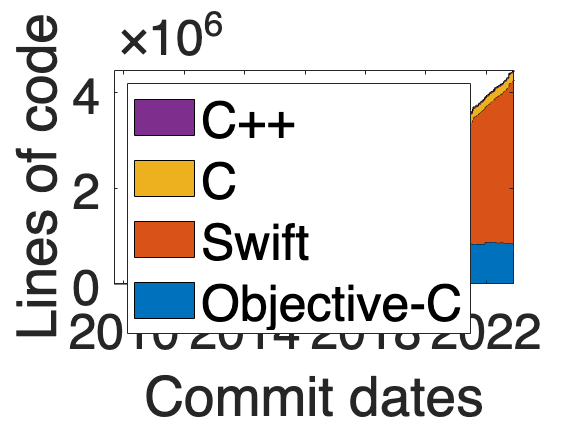

clear swiftFix1 objcFix1 CFix1 CppFix1 datesFix
swiftFix1 = [];
objcFix1 = [];
CFix1 = [];
CppFix1 = [];
datesFix = NaT;

for vc = setdiff(1:size(data), 9)
    dates = NaT;
    swift = [];
    objc = [];
    cpp = [];
    c = [];

    for j = 1:length(data{vc, 10})
        dates(j) = data{vc,10}(j).dateTime;
        if isfield(data{vc, 10}(j), "languagePercentagesCloc")
            if (isfield(data{vc,10}(j).languagePercentagesCloc, "Swift"))
                swift(j) = data{vc,10}(j).languagePercentagesCloc.Swift.code; 
            else
                swift(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).languagePercentagesCloc, "C"))
                c(j) = data{vc,10}(j).languagePercentagesCloc.C.code;
            else
                c(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).languagePercentagesCloc, "Objective_C"))
                objc(j) = data{vc,10}(j).languagePercentagesCloc.Objective_C.code;
            else
                objc(j) = 0;
            end

            if (isfield(data{vc,10}(j).languagePercentagesCloc, "C__"))
                cpp(j) = data{vc,10}(j).languagePercentagesCloc.C__.code;
            else
                cpp(j) = 0;
            end
        else
            swift(j) = 0;
            objc(j) = 0;
            cpp(j) = 0;
            c(j) = 0;
        end
    end

    swift = swift(1:end);
    objc = objc(1:end);
    cpp = cpp(1:end);
    c = c(1:end);

    an = swift;
    for i=2:length(swift)
        an(i) = swift(i) - swift(i-1);
    end

    bn = objc;
    for i=2:length(objc)
        bn(i) = objc(i) - objc(i-1);
    end

    cn = c;
    for i=2:length(c)
        cn(i) = c(i) - c(i-1);
    end

    dn = cpp;
    for i=2:length(cpp)
        dn(i) = cpp(i) - cpp(i-1);
    end

    swiftFix1 = [swiftFix1; an'];
    objcFix1 = [objcFix1; bn'];
    CFix1 = [CFix1; cn'];
    CppFix1 = [CppFix1; dn'];
    datesFix = [datesFix, dates(1:end)];
end

datesFix = datesFix';
datesFix = datesFix(2:end);

[datesFix, idx] = sort(datesFix, 'ascend');
swiftFix1 = swiftFix1(idx, :);
objcFix1 = objcFix1(idx, :);
CFix1 = CFix1(idx, :);
CppFix1 = CppFix1(idx, :);

swiftFix1 = cumsum(swiftFix1);
objcFix1 = cumsum(objcFix1);
CFix1 = cumsum(CFix1);
CppFix1 = cumsum(CppFix1);

figure;
area(datesFix, [objcFix1, swiftFix1, CFix1, CppFix1]);
xlim([datesFix(1) datesFix(end)])
hold off;

% Creating legend at the top-left and increasing font size
lgd = legend("Objective-C", "Swift", "C", "C++", 'Location', 'northwest');
set(lgd, 'FontSize', 25);

% Increasing font size for axis labels
xlabel('Commit dates', 'FontSize', 25);
ylabel('Lines of code', 'FontSize', 25);

% Optionally, increase the font size for the axes tick labels
set(gca, 'FontSize', 25);
% Get the position of the figure
fig_pos = get(gcf, 'Position');

% Set the paper size to the figure size and adjust the position
set(gcf, 'PaperUnits', 'points');
set(gcf, 'PaperSize', [fig_pos(3), fig_pos(4)]);
set(gcf, 'PaperPosition', [0, 0, fig_pos(3), fig_pos(4)]);


print(gcf, 'lang-distr', '-dpdf', '-r0');